% Main script to run Experiment 1: SIFT + SVM (Whole Image)

## Clean environment

close all;
clear variables;
clc;

## Enables GPU

[device, useGPU] = enableGPU();

✅ GPU found and ready:
  CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589410304 (8.59 GB)
      AvailableMemory: 7443034112 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

## Set folder path

folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assignment_1\data\CUB_200_2011_Subset20classes\";

## Load dataset

[trainingImageNames, validationImageNames, testImageNames, classNames, imageClassLabels] = loadDataset(folder);

## Create datastores


trainingImageDS = createImageDatastore(trainingImageNames, folder);
disp('Training set class distribution:');

Training set class distribution:


countEachLabel(trainingImageDS);

validationImageDS = createImageDatastore(validationImageNames, folder);
disp('Validation set class distribution:');

Validation set class distribution:


countEachLabel(validationImageDS);

testImageDS = createImageDatastore(testImageNames, folder);
disp('Test set class distribution:');

Test set class distribution:


countEachLabel(testImageDS);

## Resize image datastores and combine them with the labels

trainCDS = resizeCombineDatastore(trainingImageDS);
valCDS = resizeCombineDatastore(validationImageDS);
testCDS = resizeCombineDatastore(testImageDS);

## Show images

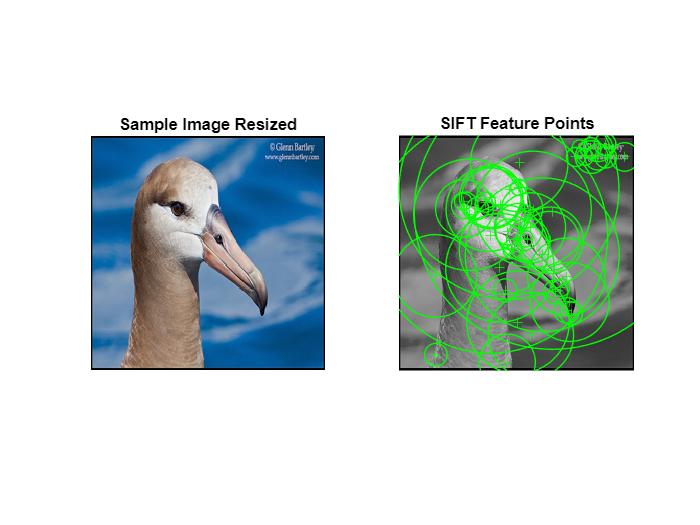

showImageFeatures(trainCDS)

## Extract SIFT features

numFeatures = 200;
maxFeatures = 1000;

[trainingFeatures, trainingLabels] = extractSIFTFeaturesFromDatastore(trainingImageDS, numFeatures, maxFeatures);
[testFeatures, testLabels] = extractSIFTFeaturesFromDatastore(testImageDS, numFeatures, maxFeatures);

## move to gpu

trainingFeatures = moveToGPU(trainingFeatures, useGPU);
testFeatures = moveToGPU(testFeatures, useGPU);
%trainingLabels = moveToGPU(trainingLabels, useGPU);
%testLabels = moveToGPU(testLabels, useGPU);

## Normalize features

[trainingFeatures, mu, sigma] = normalizeFeatures(trainingFeatures);
testFeatures = normalizeFeatures(testFeatures, mu, sigma);

## Train classifier

Starting parallel pool (parpool) using the 'Processes' profile ...
26-Apr-2025 13:59:32: Job Queued. Waiting for parallel pool job with ID 1 to start ...
Connected to parallel pool with 8 workers.
Copying objective function to workers...
Done copying objective function to workers.


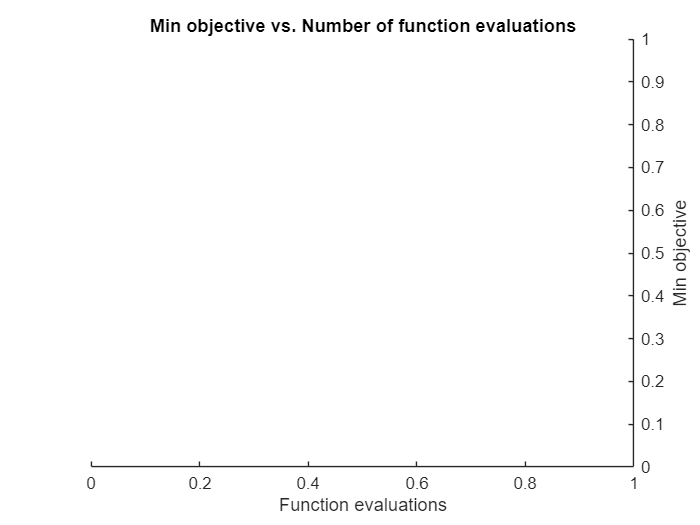

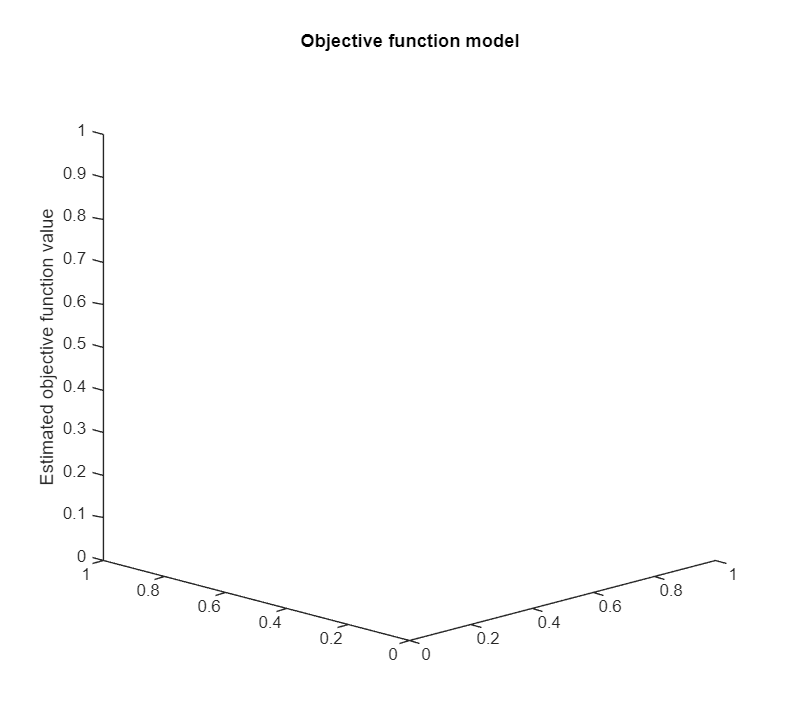

SVMClassifier = trainSVMClassifier(trainingFeatures, trainingLabels);

## Evaluate

[accuracy, predictions] = evaluateClassifier(SVMClassifier, testFeatures, testLabels);

## move back from GPU

predictions = gatherFromGPU(predictions, useGPU);
accuracy = gatherFromGPU(accuracy, useGPU);

## Plot confusion matrix

plotConfusionMatrix(testLabels, predictions, "Overall Accuracy (SIFT): " + string(round(accuracy*100, 1)) + "%");